load('pathdata.mat');

num_agents = 2;
num_steps = 130;

% Leader path
x_pos = leader_pos_store(:,1)';
y_pos = leader_pos_store(:,2)';
x_vel = leader_vel_store(:,1)';
y_vel = leader_vel_store(:,2)';

% Initialize agent positions and velocities
p_1 = [-5; -1];
p_2 = [-5;  1];
p = [p_1'; p_2'];
v = zeros(num_agents, 2);

% Initialize leader
p_leader_current = [-4, 0];
v_leader_current = [-4, 0];

% Store agent trajectories
for i = 1:num_agents
    eval(sprintf('p_%d = [p(%d, :)''];', i, i));
    eval(sprintf('v_%d = [v(%d, :)''];', i, i));
end

% Store vector field snapshots every 13 steps
field_steps = [];
p_field = {};
v_field = {};
p_leader_field = {};
v_leader_field = {};

collision_count = 0;

for i = 1:num_steps
    % Swarm logic
    N = neighbor_calc(p, num_agents);
    v = agent_velocity(N, p, v, p_leader_current, v_leader_current, num_agents);
    p = position_update(p, v);

    for j = 1:num_agents
        eval(sprintf('p_%d(:, end+1) = p(%d, :)'';', j, j)); 
        eval(sprintf('v_%d(:, end+1) = v(%d, :)'';', j, j));
    end

    % Update leader
    p_leader_current = [x_pos(i), y_pos(i)];
    v_leader_current = [x_vel(i), y_vel(i)];

    % Collision checking
    collision_radius = 0.05;
    collisions = check_collisions(p, collision_radius);
    if any(collisions(:))
        collision_count = collision_count + 1;
    end

    % Save data every 13 steps
    if mod(i-1, 13) == 0
        field_steps(end+1) = i;
        p_field{end+1} = p;
        v_field{end+1} = v;
        p_leader_field{end+1} = p_leader_current;
        v_leader_field{end+1} = v_leader_current;
    end
end

disp(['Total Collision Count: ', num2str(collision_count)]);

Total Collision Count: 0


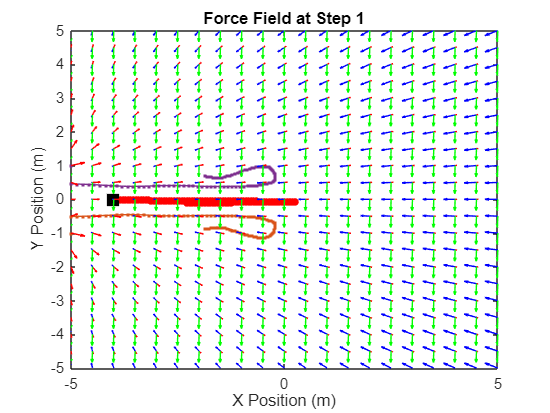

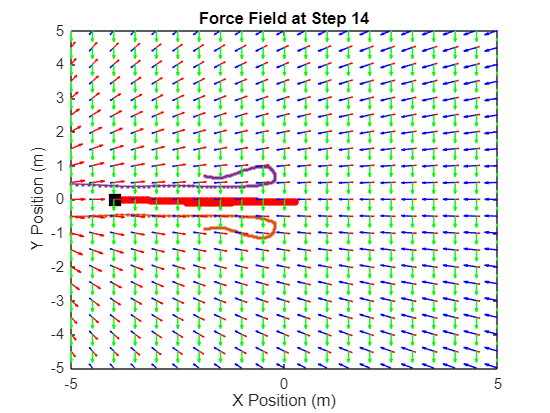

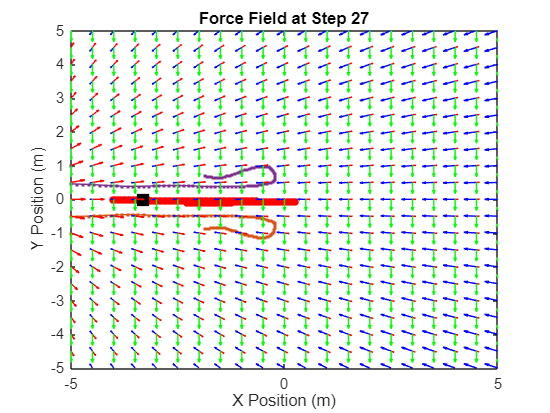

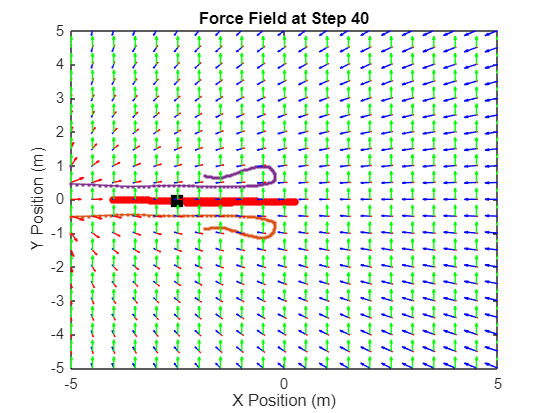

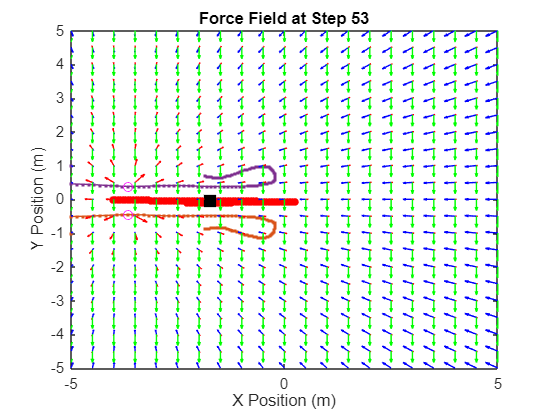

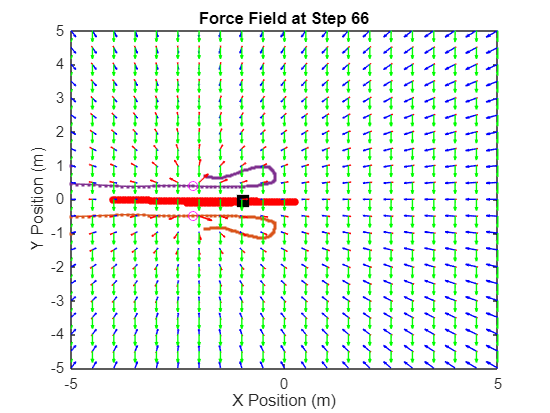

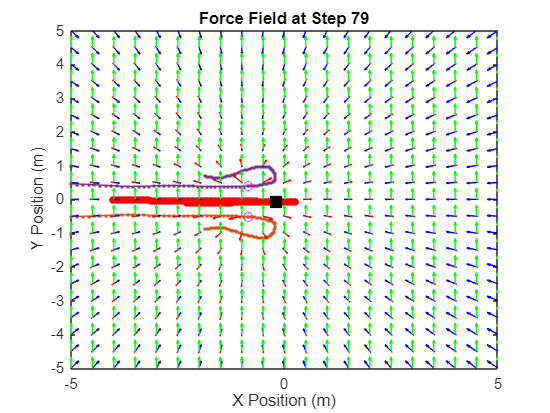

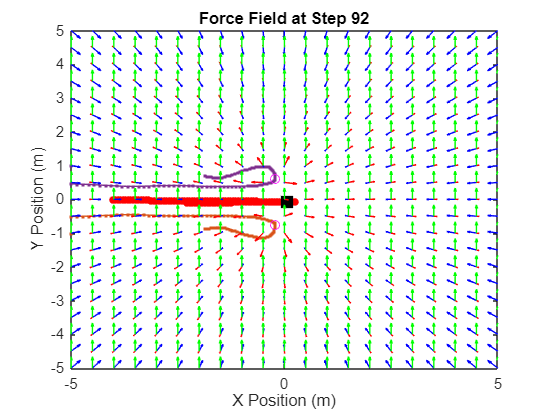


% Force parameters
k_c = 0.05;
k_a = 0.1;
k_s = 0.8;
r_0 = 0.9;
k_avoid = 0.8;

% Grid for force field
[x_grid, y_grid] = meshgrid(-5:0.5:5, -5:0.5:5);

% Plot vector fields after simulation
for idx = 1:length(field_steps)
    p_now = p_field{idx};
    v_now = v_field{idx};
    p_leader_now = p_leader_field{idx};
    v_leader_now = v_leader_field{idx};

    u_sep = zeros(size(x_grid));
    v_sep = zeros(size(y_grid));
    u_coh = zeros(size(x_grid));
    v_coh = zeros(size(y_grid));
    u_align = zeros(size(x_grid));
    v_align = zeros(size(y_grid));

    for ix = 1:size(x_grid, 1)
        for iy = 1:size(y_grid, 2)
            hypothetical_pos = [x_grid(ix, iy), y_grid(ix, iy)];

            F_sep = zeros(1, 2);
            F_coh = zeros(1, 2);
            F_align = zeros(1, 2);

            for k = 1:num_agents
                r_vec = hypothetical_pos - p_now(k, :);
                r = norm(r_vec) + 1e-6;
                F_sep = F_sep + k_s * (r_vec / r) * log(1 + r_0 / r);
                F_coh = F_coh + k_c * (p_now(k, :) - hypothetical_pos);
                F_align = F_align + k_a * (v_now(k, :) - v_now(1, :));
            end

            % Optional: include leader influence
            % F_leader = k_c * (p_leader_now - hypothetical_pos) + k_a * (v_leader_now - v_now(1, :));
            % F_coh = F_coh + F_leader;

            u_sep(ix, iy) = F_sep(1); v_sep(ix, iy) = F_sep(2);
            u_coh(ix, iy) = F_coh(1); v_coh(ix, iy) = F_coh(2);
            u_align(ix, iy) = F_align(1); v_align(ix, iy) = F_align(2);
        end
    end

    % Plot the vector fields
    figure;
    plot(x_pos, y_pos, 'r.-', 'MarkerSize', 15); 
    hold on;

    for j = 1:num_agents
        eval(sprintf('plot(p_%d(1,:), p_%d(2,:), ''.-'');', j, j));
        plot(p_now(j, 1), p_now(j, 2), 'mo');
    end

    plot(p_leader_now(1), p_leader_now(2), 'ks', 'MarkerSize', 10, 'MarkerFaceColor', 'k');

    quiver(x_grid, y_grid, u_sep, v_sep, 'r', 'AutoScaleFactor', 0.5);
    quiver(x_grid, y_grid, u_coh, v_coh, 'b', 'AutoScaleFactor', 0.5);
    quiver(x_grid, y_grid, u_align, v_align, 'g', 'AutoScaleFactor', 0.5);

    xlabel('X Position (m)');
    ylabel('Y Position (m)');
    axis([-5, 5, -5, 5]);
    title(sprintf('Force Field at Step %d', field_steps(idx)));
    hold off;
end